load fisheriris
X = meas(:,2:4);
size(X)

ans =    150     3


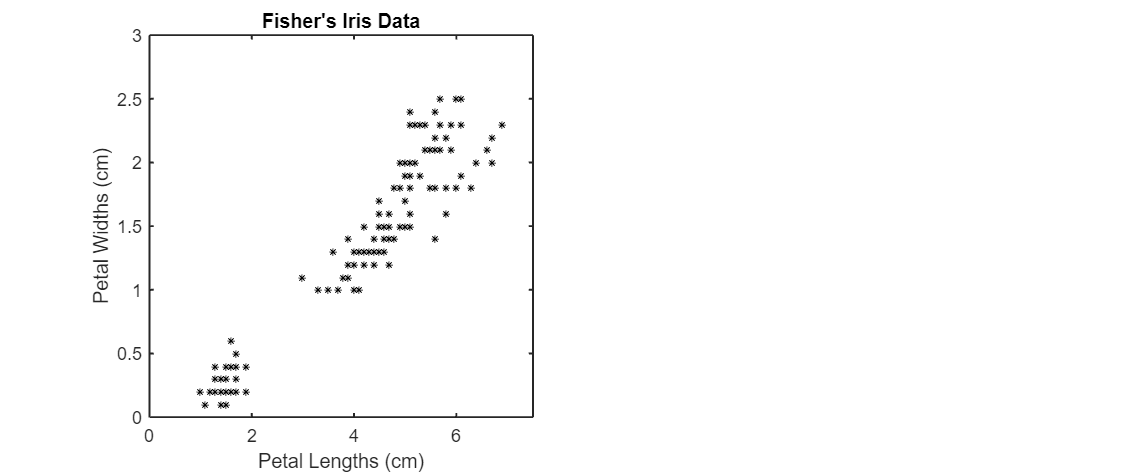

figure('Position', [448 442 1020 420]);
subplot(1,2,1);
plot(X(:,2),X(:,3),'k*','MarkerSize',5);
title('Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel('Petal Widths (cm)');
set(gca,'FontSize',12,'LineWidth',1.25,'YLim',[0, 3],'XLim',[0, 7.5],'Layer','Top')

% compute A with eucidean distance
r = 2;
metric = 'euclidean';

A = computeA(X, r, metric)

A =          0    0.1021    0.0622    0.0810    0.0204    0.0917    0.0173    0.0200    0.1225    0.0841    0.0418    0.0204    0.1053    0.1085    0.1008    0.1911    0.0873    0.0036    0.0681    0.0655    0.0216    0.0486    0.0234    0.0335    0.0257    0.1008    0.0168    0.0040    0.0204    0.0602    0.0805    0.0151    0.1201    0.1429    0.0810    0.0633    0.0040    0.0173    0.1029    0.0200    0.0033    0.2426    0.0622    0.0205    0.0752    0.0989    0.0633    0.0613    0.0418    0.0408
    0.1021         0    0.0403    0.0216    0.1225    0.1931    0.0849    0.0825    0.0204    0.0181    0.1437    0.0836    0.0036    0.0146    0.2028    0.2931    0.1894    0.1053    0.1694    0.1674    0.0848    0.1503    0.1204    0.0751    0.0878    0.0080    0.0903    0.1029    0.0817    0.0431    0.0233    0.0891    0.2222    0.2450    0.0216    0.0401    0.1014    0.1193    0.0040    0.0825    0.1045    0.1405    0.0403    0.1174    0.1751    0.0036    0.1651    0.0408    0.1437    0

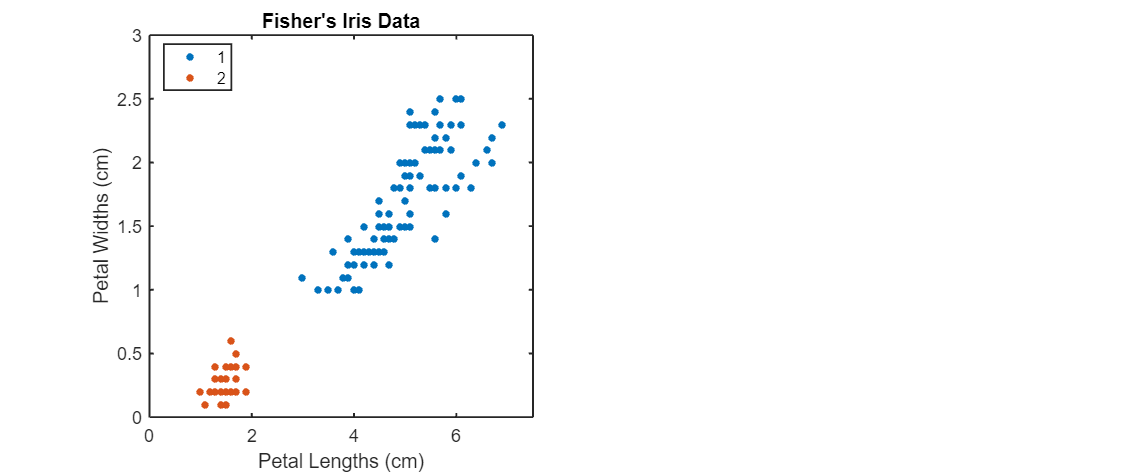

% cluster and visualize
k = 2;
clusters = spectralcluster(A, k);
gscatter(X(:,2),X(:,3), clusters)
title('Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel('Petal Widths (cm)');
set(gca,'FontSize',12,'LineWidth',1.25,'YLim',[0, 3],'XLim',[0, 7.5],'Layer','Top')